# Actividad 5: DataPort + Matriz de correlacion

**Simulación de Sistemas Eléctricos**

Nombres:

- Estudiante 1: VA

- Estudiante 2: VA

Contenido:

- Codigo de ejemplo: [https://github.com/vasanza/EnergyConsumptionPrediction/blob/master/main.pdf](https://github.com/vasanza/EnergyConsumptionPrediction/blob/master/main.pdf)

- Descargar datos (.mat) desde desde repositorio (DataPort)

- [https://ieee-dataport.org/competitions/2-phase-energy-meter-100a-2pem-100a](https://ieee-dataport.org/competitions/2-phase-energy-meter-100a-2pem-100a)

- Almacenar el archivo dataset.m en la carpeta ./data

- **1.- Leer el archivo usando Matlab y graficar los datos**

- **2.- Normalizar los datos usando la funcion fNormalization**

- **3.- Graficar la matriz de correlación**

- [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- **Nota:** realizar cualquier cambio que usted considere adecuado

#### **1.- Eliminar datos de memoria y command window**

clear; %Borrar el korspace
clc; %Borrar el command window

#### 2.- Configuración de carpeta /src para librerias

%nombre de la carpeta donde estan los codigos
addpath(genpath('./src'));

#### 3- Cargar dataset desde carpeta ./data

path=fullfile('./data/dataset.mat');
data=load(path); % Estructura
data=data.data; %Table

dataArray=table2array(data(:,4:12));%Arreglo numérico de datos int, foat or double

Voltaje=dataArray(:,1);
Corriente=dataArray(:,2);
Potencia=dataArray(:,3);
Energia=dataArray(:,5);

#### 4.- Graficar todas las Variables en raw

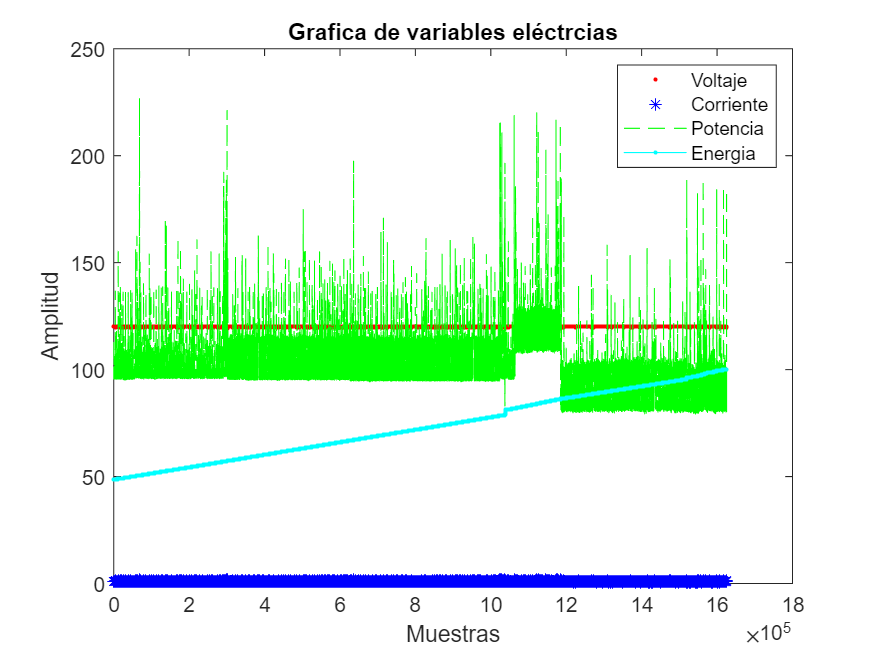

figure %crear una nueva grafica
plot(Voltaje,'r.') %plotea la grafica 1
hold on %habilita plotear mas de una grafica en la misma figura
plot(Corriente,'b*') %plotea la grafica 2
plot(Potencia,'g--') %plotea la grafica 3
plot(Energia,'c.-') %plotea la grafica 4
hold off

title('Grafica de variables eléctrcias');
xlabel('Muestras');
ylabel('Amplitud');
legend('Voltaje','Corriente','Potencia','Energia');

**5.- Grafica de datos normalizados**

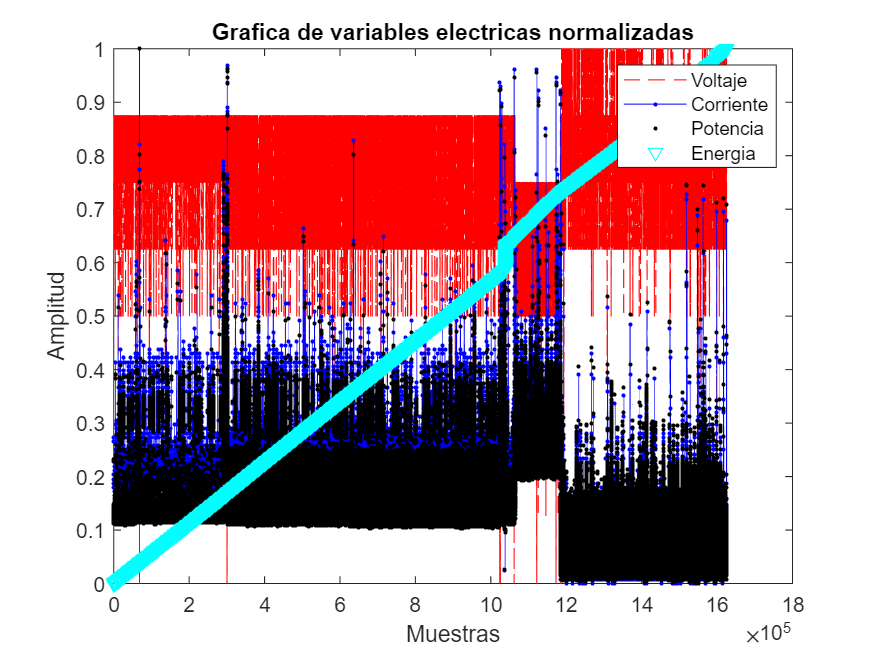

[dataArrayNorm] = fNormalization(dataArray);

VoltajeNorm=dataArrayNorm(:,1);
CorrienteNorm=dataArrayNorm(:,2);
PotenciaNorm=dataArrayNorm(:,3);
EnergiaNorm=dataArrayNorm(:,5);

figure %crear una nueva grafica
plot(VoltajeNorm,'r--') %plotea la grafica 1
hold on %habilita plotear mas de una grafica en la misma figura
plot(CorrienteNorm,'b.-') %plotea la grafica 2
plot(PotenciaNorm,'k.') %plotea la grafica 3
plot(EnergiaNorm,'cv') %plotea la grafica 4
hold off

title('Grafica de variables electricas normalizadas');
xlabel('Muestras');
ylabel('Amplitud');
legend('Voltaje','Corriente','Potencia','Energia');

**6.- Grafica la matriz de correlación**

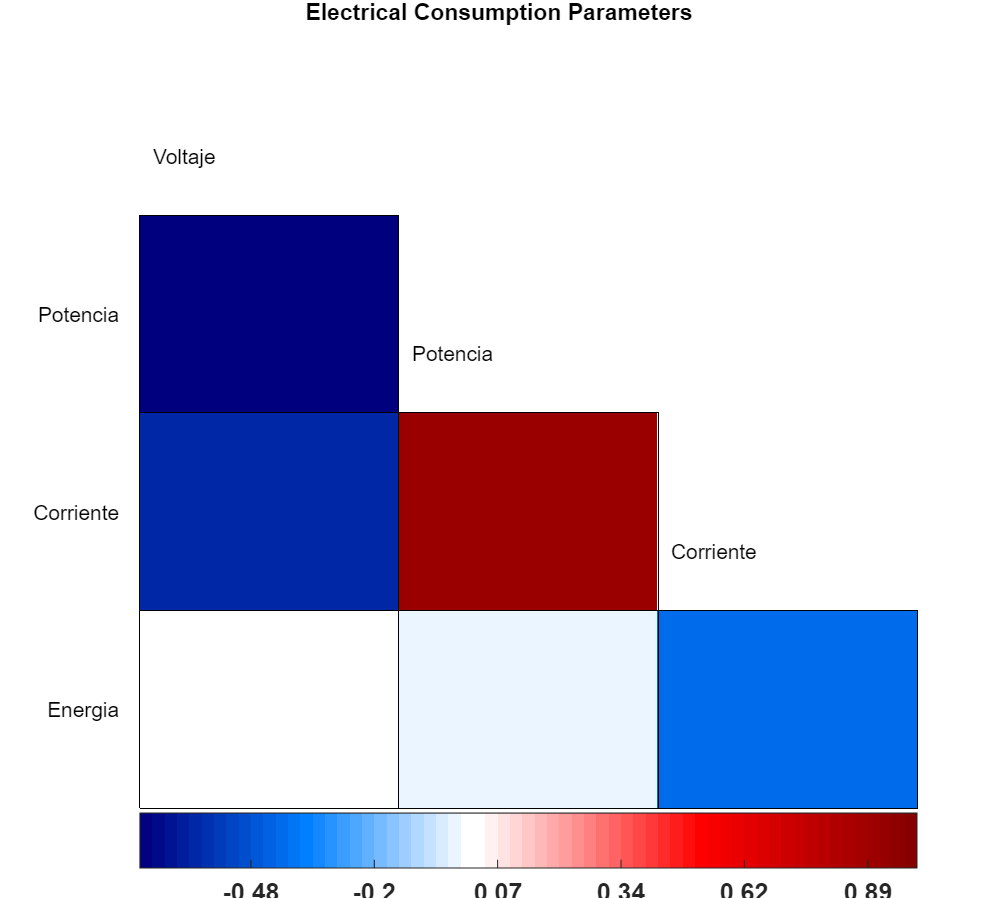

NewDataFeatures =     0.7500    0.1875         0
    0.7500    0.2656         0
    0.7500    0.2656         0
    0.7500    0.2031         0
    0.7500    0.1875         0
    0.7500    0.1875         0
    0.7500    0.1797         0
    0.7500    0.1797         0
    0.7500    0.1875         0
    0.7500    0.1875         0


NewFeaturesLabels = 1×3 cell array
    {'Voltaje'}    {'Corriente'}    {'Energia'}


LabelsRemove = 1×1 cell array
    {'Potencia'}


threshold=0.85;
DataFeatures=[VoltajeNorm CorrienteNorm PotenciaNorm EnergiaNorm];
FeaturesLabels={'Voltaje','Corriente','Potencia','Energia'};
[NewDataFeatures,NewFeaturesLabels,LabelsRemove] = Feature_Selection(DataFeatures,FeaturesLabels,threshold)